# Lagrange demo (simbolic)

Să se determine polinomul de interpolare Lagrange pentru funcția $f(x)=\sin(x)$ și nodurile

$x=\left\lbrack 0, \frac{\pi}{6}, \frac{\pi}{4}, \frac{\pi}{3}, \frac{\pi}{2}, \pi \right\rbrack$.

close all
syms t
Pi=sym(pi);
x=sym([0,Pi/6, Pi/4, Pi/3, Pi/2,Pi]);
y=sin(x);
P=Lagrange(x,y,t)

$$P = \frac{3888\,t\,\left(-\pi +t\right)\,\left(-\frac{\pi }{2}+t\right)\,\left(-\frac{\pi }{3}+t\right)\,\left(-\frac{\pi }{4}+t\right)}{5\,\pi^{5}}-\frac{288\,t\,\left(-\pi +t\right)\,\left(-\frac{\pi }{3}+t\right)\,\left(-\frac{\pi }{4}+t\right)\,\left(-\frac{\pi }{6}+t\right)}{\pi^{5}}-\frac{1536\,\sqrt{2}\,t\,\left(-\pi +t\right)\,\left(-\frac{\pi }{2}+t\right)\,\left(-\frac{\pi }{3}+t\right)\,\left(-\frac{\pi }{6}+t\right)}{\pi^{5}}+\frac{972\,\sqrt{3}\,t\,\left(-\pi +t\right)\,\left(-\frac{\pi }{2}+t\right)\,\left(-\frac{\pi }{4}+t\right)\,\left(-\frac{\pi }{6}+t\right)}{\pi^{5}}$$

Reprezentarea grafică

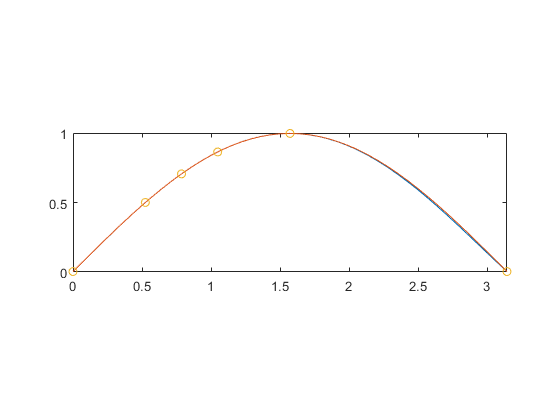

fplot(P,[0,pi])
hold on
fplot(@(t) sin(t),[0,pi])
plot(x,y,'o')
axis equal
hold off

O reprezentare a restului

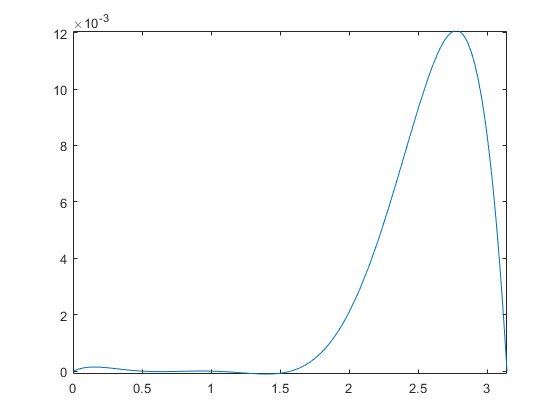

fplot(sin(t)-P,[0,pi])

Dăm codul pentru Lagrange (funcționează și în mod numeric și simbolic):